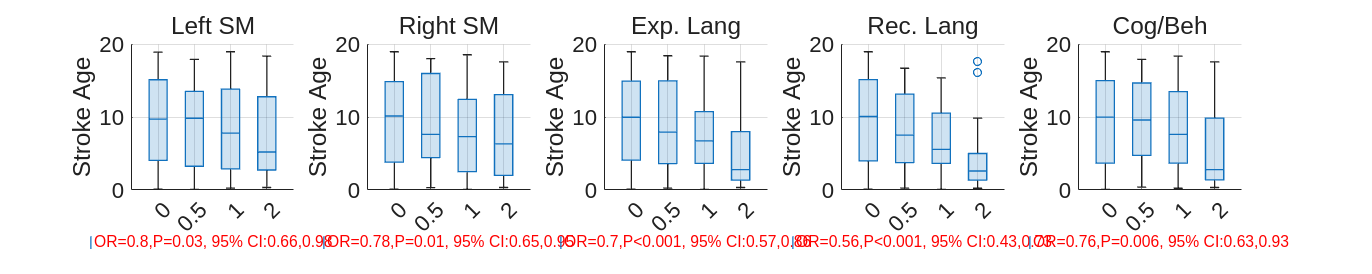

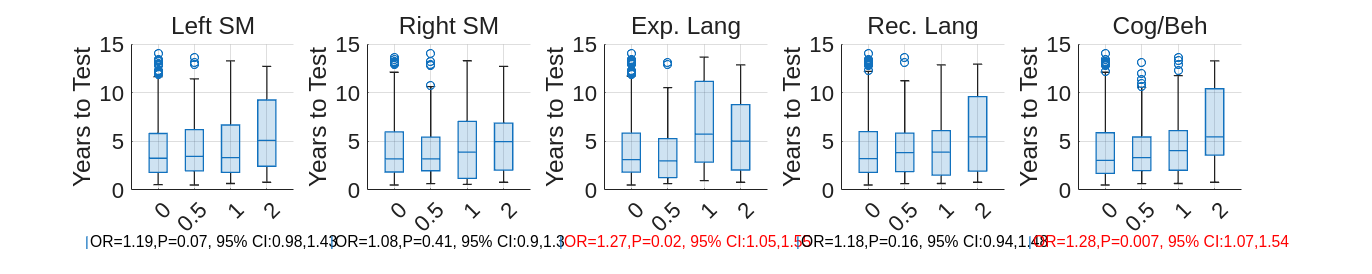

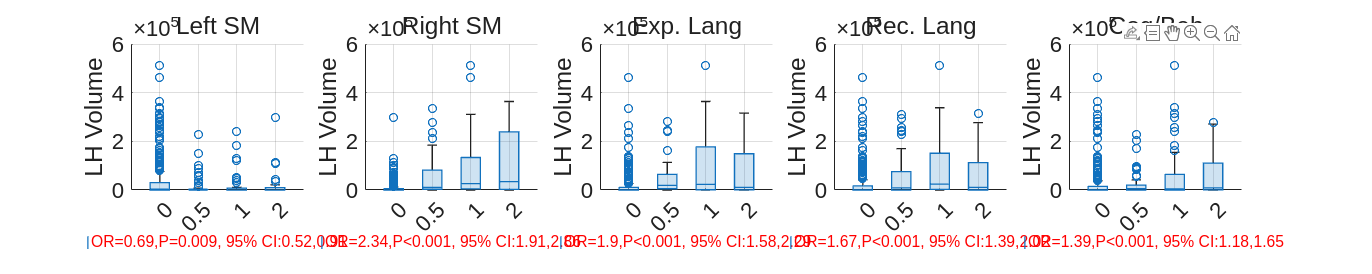

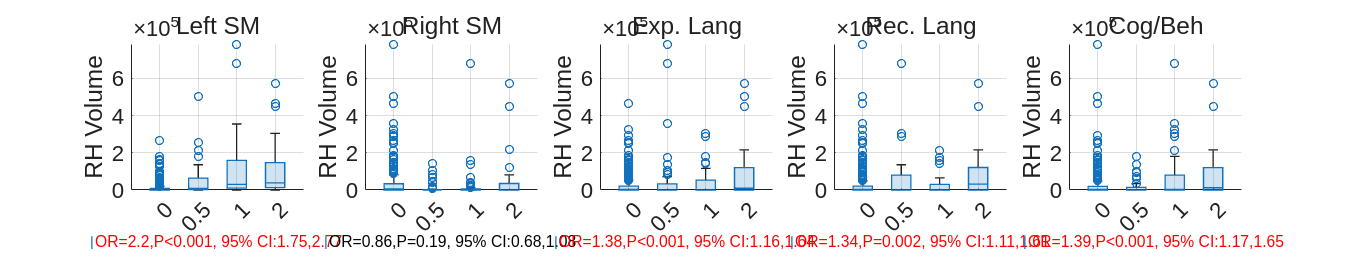

clear all;

% Inclusion criteria
min_stroke_age = 0; % Any onset age
min_test_age = 0; % Any test age
min_test_interval = 0.5; % at least 6 months post-onset interval to test

% Get VIPS dataset
project_dir = '/Shared/boeslab/Users/jcgriffis/vips_psom_mapping';
beh_csv = readtable(fullfile(project_dir, 'behavior', 'vips_combined_31226.csv'), 'Format', 'auto');
beh_csv = beh_csv(beh_csv.stroke_age >= min_stroke_age,:);
beh_csv = beh_csv(beh_csv.test_age >= min_test_age,:);
beh_csv = beh_csv(beh_csv.yrs2test >= min_test_interval, :);
beh_csv = beh_csv(beh_csv.has_lesion == 1,:);

% Make box plots of stroke onset age at each level of impairment
my_vars = {'stroke_age', 'yrs2test', 'lh_vol', 'rh_vol'};
var_names = {'Stroke Age', 'Years to Test', 'LH Volume', 'RH Volume'};
domains = {'Left', 'Right', 'Verbal', 'LanguageReception','Cognitive_Behavioral'};
my_names = {'Left SM', 'Right SM', 'Exp. Lang', 'Rec. Lang', 'Cog/Beh'};

for j = 1:length(my_vars)
    figure;
    clf;
    tiledlayout(1,5);    
    for i = 1:length(domains)

        % Recode outcome so that reference group is unimpaired
        Y = zeros(length(beh_csv.(domains{i})),1);
        Y(beh_csv.(domains{i}) == 2) = 0;
        Y(beh_csv.(domains{i}) == 1) = 1;
        Y(beh_csv.(domains{i}) == 0.5) = 2;
        Y(beh_csv.(domains{i}) == 0) = 3;    
        N = length(Y);
    
        % Age only
        mdl = fitmnr(zscore(beh_csv.(my_vars{j})), Y, 'ModelType', 'ordinal');
        aor = exp(mdl.Coefficients.Value(4));
        coeff_ci = coefCI(mdl);
        aor_ci = exp(coeff_ci(4,:));

        % Plot
        nexttile;
        b = boxchart(categorical(beh_csv.(domains{i})), beh_csv.(my_vars{j}));
        grid on; ylabel(var_names{j});
        title([my_names{i}], 'FontSize', 14, 'FontWeight','normal');
        set(gca, 'FontSize', 17);
        p = mdl.Coefficients.pValue(4); %kruskalwallis(beh_csv.(my_vars{j}), beh_csv.(domains{i}), 'off');
        if p >= 0.01
            p = round(p,2);
        elseif p<0.01 && p>=0.001
            p = round(p,3);
        elseif p<0.001
            p = 0.001; 
        end
        if p <= 0.05
            lgd=legend(['OR=' num2str(round(aor,2)), ',P=' num2str(p), ', 95% CI:' num2str(round(aor_ci(1),2)) ',' num2str(round(aor_ci(2),2))], 'FontSize', 12, 'Location', 'southoutside', 'TextColor', 'r');       
            if p <=0.001
               lgd=legend(['OR=' num2str(round(aor,2)), ',P<' num2str(p), ', 95% CI:' num2str(round(aor_ci(1),2)) ',' num2str(round(aor_ci(2),2))], 'FontSize', 12, 'Location', 'southoutside', 'TextColor', 'r');       
            end
        else
            lgd=legend(['OR=' num2str(round(aor,2)), ',P=' num2str(p), ', 95% CI:' num2str(round(aor_ci(1),2)) ',' num2str(round(aor_ci(2),2))], 'FontSize', 12, 'Location', 'southoutside', 'TextColor', 'k');       
        end            
        lgd.IconColumnWidth = 0.001;
        legend('box', 'off');

    end
    set(gcf, 'position', [0, 0, 2000, 400]);
end

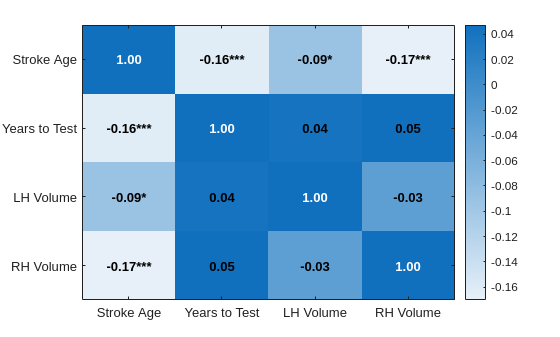

% Compute correlation coefficients and p-values
[R, P] = corrcoef([beh_csv.stroke_age, beh_csv.yrs2test, beh_csv.lh_vol, beh_csv.rh_vol]);
n = size(R, 1);

% Plot color-coded matrix
figure;
imagesc(R);
colormap('sky');
clim([min(R(:)), max(R(~eye(4,4)==1))]);
colorbar;

% Configure axes labels
xticks(1:n);
yticks(1:n);
xticklabels(var_names);
yticklabels(var_names);

% Overlay correlation values and significance stars
for i = 1:n
    for j = 1:n
        % Determine significance stars (skip diagonal)
        stars = '';
        if i ~= j
            if P(i, j) < 0.001
                stars = '***';
            elseif P(i, j) < 0.01
                stars = '**';
            elseif P(i, j) < 0.05
                stars = '*';
            end
        end
        
        % Format label and choose contrasting text color
        label = sprintf('%.2f%s', R(i, j), stars);
        textColor = 'k';
        if abs(R(i, j)) > 0.6
            textColor = 'w';
        end
        
        text(j, i, label, 'HorizontalAlignment', 'center', ...
            'Color', textColor, 'FontWeight', 'bold');
    end
end